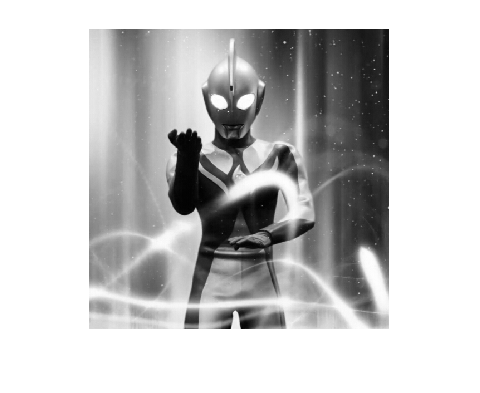

clear
clc
img = imread('test_img.jpg');
gray = rgb2gray(img);
imshow(gray);

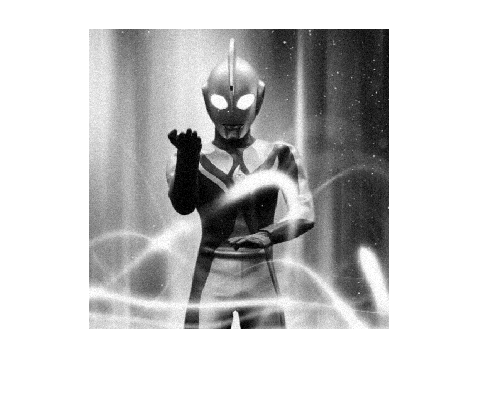

noise = randn(size(gray));
noisy_img = imnoise(gray,'gaussian',0,0.001);
imshow(noisy_img)

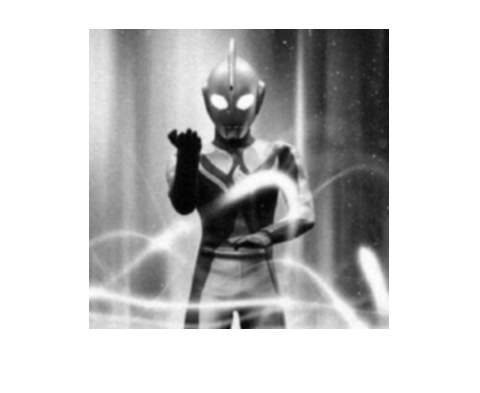

fsize = 5;
sig = 1;
kernel = fspecial('gaussian',fsize,sig);
filtered = imfilter(noisy_img,kernel,'symmetric');
imshow(filtered)